clear 
clc

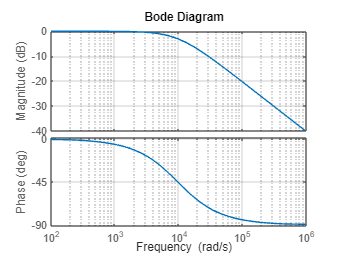

%RC filter parameters
R1 = 47; %ohm
C1 = 2.2*10^-6; %farad
%RLC filter parameters
R2 = 220; %ohm
C2 = 4.7*10^-9; %farad
L2 = 1*10^-3; %henry
%RC excitation signals
y11 = load("20210305-RC_Chirp40v150kHz_T2s.mat");
A11 = y11.A;
B11 = y11.B;
A11(isnan(A11)) = 0;
B11(isnan(B11)) = 0;
A11(isinf(A11)) = 0;
B11(isinf(B11)) = 0;
y12 = load("20210305-RC_SzumBand200kHz_T2s.mat");
A12 = y12.A;
B12 = y12.B;
A12(isnan(A12)) = 0;
B12(isnan(B12)) = 0;
A12(isinf(A12)) = 0;
B12(isinf(B12)) = 0;
%RLC excitation signals
y21 = load("20220401-RLC_Chirp1v300kHz_T2s.mat");
A21 = y21.A;
B21 = y21.B;
A21(isnan(A21)) = 0;
B21(isnan(B21)) = 0;
A21(isinf(A21)) = 0;
B21(isinf(B21)) = 0;
y22 = load("20220401-RLC_SzumBand500kHz_T2.mat");
A22 = y22.A;
B22 = y22.B;
A22(isnan(A22)) = 0;
B22(isnan(B22)) = 0;
A22(isinf(A22)) = 0;
B22(isinf(B22)) = 0;
%RC filter
Y1=[1/(R1*C1)];
V1=[1 1/(R1*C1)];
sys1=tf(Y1,V1);
%RLC filter
Y2=[R2/L2 0];
V2=[1 R2/L2 1/(C2*L2)];
sys2=tf(Y2,V2);
%bode plot of the RC system
[mag1,phase1,w1]=bode(sys1);
bode(sys1), grid on

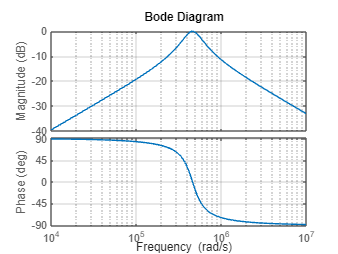

%bode plot of the RLC system
[mag2,phase2,w2]=bode(sys2);
bode(sys2), grid on

%finding resonant frequency and damping (half power method) for RC


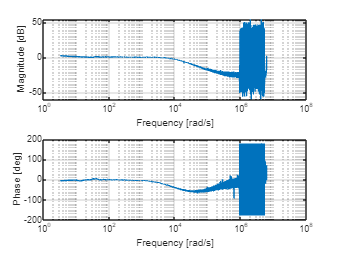

%plotting bode for the acquired signal (RC)
fA11=fft(A11);
fB11 = fft(B11);
H11 = fA11./fB11;
N11=length(H11);
f11=2*pi*1/y11.Tinterval*(0:(N11-1))/N11;
mag_sys11=abs(H11);
phase_deg11=rad2deg(angle(H11));

figure()
subplot(2,1,1);
semilogx(f11,20*log10(mag_sys11)), grid on
xlabel('Frequency [rad/s]')
ylabel('Magnitude [dB]')
subplot(2,1,2);
semilogx(f11,phase_deg11), grid on
xlabel('Frequency [rad/s]')
ylabel('Phase [deg]')

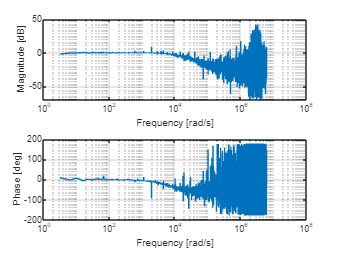

fA12=fft(A12);
fB12 = fft(B12);
H12 = fA12./fB12;
N12=length(H12);
f12=2*pi*1/y12.Tinterval*(0:(N12-1))/N12;
mag_sys12=abs(H12);
phase_deg12=rad2deg(angle(H12));

figure()
subplot(2,1,1);
semilogx(f12,20*log10(mag_sys12)), grid on
xlabel('Frequency [rad/s]')
ylabel('Magnitude [dB]')
subplot(2,1,2);
semilogx(f12,phase_deg12), grid on
xlabel('Frequency [rad/s]')
ylabel('Phase [deg]')

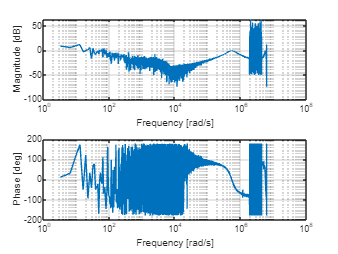

%plotting bode for the acquired signal (RLC)
fA21=fft(A21);
fB21 = fft(B21);
H21 = fA21./fB21;
N21=length(H21);
f21=2*pi*1/y21.Tinterval*(0:(N21-1))/N21;
mag_sys21=abs(H21);
phase_deg21=rad2deg(angle(H21));

figure()
subplot(2,1,1);
semilogx(f21,20*log10(mag_sys21)), grid on
xlabel('Frequency [rad/s]')
ylabel('Magnitude [dB]')
subplot(2,1,2);
semilogx(f21,phase_deg21), grid on
xlabel('Frequency [rad/s]')
ylabel('Phase [deg]')

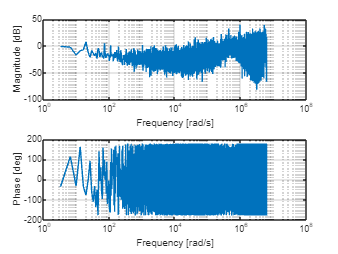

fA22=fft(A22);
fB22 = fft(B22);
H22 = fA22./fB22;
N22=length(H22);
f22=2*pi*1/y22.Tinterval*(0:(N22-1))/N22;
mag_sys22=abs(H22);
phase_deg22=rad2deg(angle(H22));

figure()
subplot(2,1,1);
semilogx(f22,20*log10(mag_sys22)), grid on
xlabel('Frequency [rad/s]')
ylabel('Magnitude [dB]')
subplot(2,1,2);
semilogx(f22,phase_deg22), grid on
xlabel('Frequency [rad/s]')
ylabel('Phase [deg]')